# Make model comparisons

There are 7 models we are comparing here:

- Linear model

- CTS model

- normalization model 1 (simplified)

- normalization model 2 (the DN model)

- cascade normalization model

- Heeger 1993 normalization model

- Horiguchi model

## set up

allROIs   = {'V1', 'V2', 'V3', 'hV4', 'VO', 'LO', 'TO', 'IPS'};
% want to extract 3 rois only: V1,  hV4, LO
mriRoi    = [1, 4, 6]; 
ecogRoi   = [1, 5, 7];
roiLabels = ['V1', 'hV4', 'LO'];
nRois     = length(mriRoi);

## make new stimuli

% to create two new predictions: one brief stimulus (50ms) and one long lasting stimulus

maxT = 2.5;
dt   = 0.001;
T    = round(maxT / dt);
t    = (1:T)*dt;
stim = zeros(2, T);

stim1Lth = round(0.05 / dt); % stim(1, 1 : stim1Lth) = 1;


lth = 50;
tmp = [ones(1, 200), zeros(1, lth)];
stim(1, :) = repmat(tmp, [1, 10]);

stim2Lth = round(maxT / dt); stim(2, 1 : stim2Lth) = 1;



## load data

dtLoc = fullfile('/Volumes', 'server', 'Projects', 'Temporal integration', 'code');
dtNm  = 'TemporalParams.mat';

if ~exist('data', 'var'),
    a     = load(fullfile(dtLoc, dtNm));
    mriData0  = squeeze(mean(mean(a.data.fmri1, 1), 3));
    ecogData0 = squeeze(mean(a.data.ecog1, 2));
end

Error using load
Unable to read file '/Volumes/server/Projects/Temporal integration/code/TemporalParams.mat'. No such file or directory.


mriData   = mriData0(mriRoi, :);
ecogData  = ecogData0(ecogRoi, :);
tProfiles = a.params.fmri1.tProfiles;
ecogStim  = a.params.ecog1.tProfiles;


prm.modality = 'ecog';
prm.default  = 0;
prm.stim     = stim(1, :);
prm.normMax = 1;
x = [];
response = normModel(x, prm, []);



## initial fits

% fit model : linear, cts, dn, heegerNorm, simpNorm, Hiroshi, (cascade)
nModels = 6;

% set fields
% fields{1} = {'scale'};
% fields{2} = {'tau1', 'exponent', 'scale'};
% fields{3} = {'tau1', 'tau2', 'n', 'sigma', 'scale', 'shift'};
fields{1} = {'tau1', 'sigma', 'alpha', 'n', 'scale'}; % heeger model
fields{2} = {'tau1', 'sigma', 'scale'}; % simpNorm
fields{3} = {'b1', 'b2', 'epsilon'}; % Hiroshi

% linear parameters
init{1} = [0.1, 0.1, dt*10, 3, 1];
init{2} = [0.01, .5, 1];
init{3} = [100, 0, 0];


## fit model to ecog data

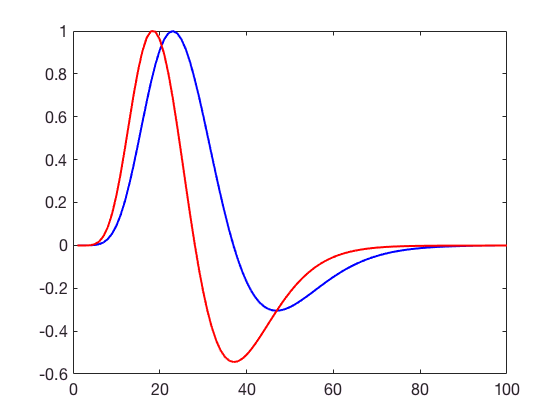

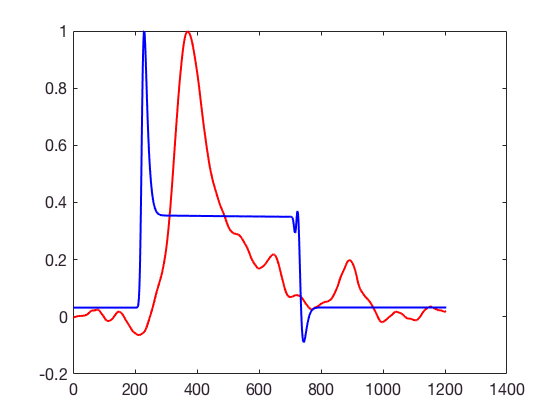

for k = 1 : nRois
    toFit = ecogData(k, :);
    %fitParam{k, 1} = fminsearch(@(x) fitHeegerModel(x, toFit, ecogStim, t, fields{1}, 2), init{1});
    fitParam{k, 2} = fminsearch(@(x) fitSimpNormModel(x, toFit, ecogStim, t, fields{2}, 2), init{2});  
    fitParam{k, 3}  = fminsearch(@(x) fitHiroshiModel(x, toFit, t, ecogStim, dt, fields{3}, 2),init{3});
end

## Compute predictions

% output is cell that has dimension 7 x 4 (7 models and 4 predictions)
output = [];

for k = 1 : nRois
    % heeger normalization model
%     x = [];
%     x = toSetField(x, fields{1}, fitParam{k, 1});
%     output{1, 2}(k, :) =  computeModel('d', x, ecogStim, t, [], dt);
%     % simplified normalization model
    s = [];
    s = toSetField(s, fields{2}, fitParam{k, 2});
    output{2, 2}(k, :) =  computeModel('s', s, ecogStim, t, [], dt);
    % Hiroshi model
    hi = [];
    hi = toSetField(hi, fields{3}, fitParam{k, 3});
    output{3, 2}(k, :) = computeModel('hi', hi, ecogStim, t, [], dt);
end


% computeModel(whichModel, param, stim, t, prm, dt)

## Visualize model to the old stim

## compute model to new stimuli

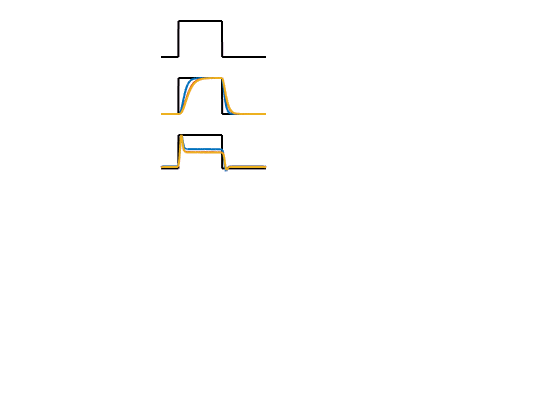

figure (1), clf, color = {'b', 'r', 'g'};
which = [2, 6, 10];
normMax = @(x) x./max(x);

% gaussian blur the last output
m = 0;
x = -1 : 0.001 : 1;
sigma = 0.01;
gau = exp(-(-.1:1/1000:.1).^2./(2*sigma^2));
for k = 1 : 3
    output{3, 2}(k, :) = normMax(conv(output{3, 2}(k, :), gau, 'same'));
end


for k = 1 : nRois
    subplot_tight(7, 4, which(k), 0.05)
    plot(ecogStim, 'k-'), hold on
    plot(output{k, 2}')
    box off, axis tight, axis off
end

% Heeger normalization ---------------------------------------------------------------------------------

function output = makeHeegerNormalization(params, stimulus, t)
    % z needs to have the following fields:
    % tau1 - time constant for linear impulse response 
    % sigma - semi-saturation constant
    % alpha - weight on feedback (0 = no feedback)
    % n     - output non-linearity exponent
    
    R = zeros(1, length(stimulus));  % Normalized response
    G = zeros(size(R));         % Feedback signal
    F = zeros(size(R));         % Multiplicative feedback
    K = 1;                      % Determines maximum responses
        
    irf     = gammaPDF(t, params.tau1, 2);
    for k = 1 : size(stimulus, 1)
        L       = convCut(stimulus(k, :), irf, length(stimulus));
        R(1) = max(L(1),0)^params.n;
        G(1) = params.alpha * R(1);
        F(1) = sqrt(K-G(1))/ params.sigma;
        
        for ii = 2:length(t)
            R(ii) = max(L(ii) * F(ii-1),0)^params.n;
            G(ii) = (1-params.alpha) * G(ii-1) + params.alpha*R(ii);
            G(ii) = min(G(ii), K);
            F(ii) = sqrt(K-G(ii-1)) / params.sigma;
        end
        output(k, :) = R./max(R);
    end
%     figure(100)
%     plot( t, L, t,R, t, G, t, F); legend('L', 'R', 'G', 'F')
end

% Fit Heeger Model --------------------------------------------------------------------
function target = fitHeegerModel(params, data, stimulus, t, fields, modality)
x      = [];
x      = toSetField(x, fields, params);
output = makeHeegerNormalization(x, stimulus, t);

if modality == 2
    target = sum((output - data).^2);
elseif modality == 1
    target = sum((sum(output)*x.scale - data).^2);
end

% figure (50), clf, plot(output, 'b-'), hold on, plot(data, 'r-')
end

% make simplified normalization model -------------------------------------------------
function output = makeSimpNormModel(params, stimulus, t)
    % parameters : sigma, n, tau1
    n = 2;
    normMax = @(x) x./max(x);
    % compute linear response
    irf    = gammaPDF(t, params.tau1, 2);
    for k = size(stimulus, 1)
        linRsp(k, :) = convCut(irf, stimulus(k, :), length(stimulus));
        num(k, :)    = linRsp.^n;
        den(k, :)    = params.sigma.^n + num(k, :);
        output(k, :) = normMax(num(k, :)./den(k, :));
    end
%     figure (99), clf, plot(num, 'b'), hold on,  plot(den, 'g'), plot(output, 'r')
end

% fit simplified normalization model -------------------------------------------------
function target = fitSimpNormModel(params, data, stimulus, t, fields, modality)
    x = [];
    x = toSetField(x, fields, params);
    output = makeSimpNormModel(x, stimulus, t);
    if modality == 2
        target = sum((output - data).^2);
    elseif modality == 1
        target = sum((sum(output)*x.scale - data).^2);
    end
%     figure (100), clf, plot(output, 'r-'), hold on, plot(data, 'b-')
end

% make Hiroshi model -----------------------------------------------------------------
function output = makeHiroshiModel(params, stimulus, t, dt)
% there are 3 parameters to be fitted: two beta weights and an epsilon

makeIRF = @(A, B, C, t)(t/A).^8 .* exp(-t/A) - 1 / B .* (t/C).^9 .* exp(-t/C);
normSum = @(x) x./sum(x);
normMax = @(x) x./max(x);

% make impulse response function
A    = 3.29;
B    = 14;
C    = 3.85;
t1   = t *(1./dt);
firf = normMax(normSum(makeIRF(A, B, C, t1)));

a = 2.75;
b = 11;
c = 3.18;
pirf = normSum(makeIRF(a, b, c, t1));
pirf = normMax(pirf - mean(pirf));

for k = 1 : size(stimulus, 1)
    fcomp(k, :)  = normSum(convCut(firf, stimulus(k, :), length(stimulus)));
    pcomp(k, :)  = normSum(convCut(pirf, stimulus(k, :), length(stimulus)).^2);
    output(k, :) = normMax(params.b1 *fcomp + params.b2 * pcomp + params.epsilon);
end
% 
figure (100), clf, 
% subplot(2, 1, 1)
plot(firf, 'b-'), hold on, plot(pirf, 'r-'), 
xlim([0, 100])
% subplot(2, 1, 2)
% plot(params.b1 *fcomp, 'b-'), hold on
% plot(params.b2 * pcomp, 'g-')
% plot(firf, 'k-'), hold on, plot(pirf, 'r-'), xlim([0, 100])
end

% Fit Hiroshi model -----------------------------------------------------------------
function target = fitHiroshiModel(params, data, t, stimulus, dt, fields, modality)
   x = [];
   x = toSetField(x, fields, params);
   output = makeHiroshiModel(x, stimulus, t, dt);
   if modality == 2
       target = sum((output - data).^2);
   elseif modality == 1
       target = sum((sum(output)*x.scale - data).^2);
   end
    figure (90), clf, plot(data, 'r-'), hold on, plot(output, 'b-')
end

% to set field ------------------------------------------------------------------------
function str = toSetField(str, fieldName, fieldVal)
for k = 1 : length(fieldName)
    str = setfield(str, fieldName{k}, fieldVal(k));
end
end

% compute each model -------------------------------------------------------------------------------
function output = computeModel(whichModel, param, stim, t, prm, dt)
for k = 1 : size(stim, 1)
    stimulus = stim(k, :);
    switch whichModel
        case 'dn'
            prm.stim     = stimulus;
            output(k, :) = normModel(param, prm, []);
        case 'd',  output(k, :) = makeHeegerNormalization(param, stimulus, t);
        case 'l',  output(k, :) = makeKenwayNormalization(param, stimulus, t);
        case 's',  output(k, :) = makeSimpNormModel(param, stimulus, t);
        case 'hi', output(k, :) = makeHiroshiModel(param, stimulus, t, dt);
    end
end
end
